## MAE 547 Final Project: Minimize Torque Effort

Purpose: This code takes a 2-link robot arm dynamics and minimizes the cost of trajectory of moving the robot arm to a specified position. The cost in this code is synonymous to torque effort. 

clear; clc; close all;

#### Physical Robot Parameters

m_l1 = 1;       % {kg}
m_l2 = 1;       % {kg}
a_1  = 1;       % {m}
l_1  = 0.5;     % {m}
l_2  = 0.5;     % {m}
I_l1 = 0.3;     % {kg*m^2}
I_l2 = 0.3;     % {kg*m^2}
g = 9.81;       % {m/s^2}

#### Initial/End Joint Angle Positions 

q0 = [30; 20]*pi/180;   % {rad}
qf = [90; 80]*pi/180;   % {rad}

Establishing a linear trajectory from start to end to optimize 

T = 2;  % {s} total time
N = 100;
t = linspace(0, T, N);
dt = t(2)-t(1);

q_ref = [linspace(q0(1), qf(1), N); linspace(q0(2), qf(2), N)];
qd_ref = [gradient(q_ref(1,:), dt); gradient(q_ref(2,:), dt)];
qdd_ref = [gradient(qd_ref(1,:), dt); gradient(qd_ref(2,:), dt)];

#### Simplifying Functions for Calling

You can call dynamics(theta, theta_dot, theta_ddot) instead of computeTorques(theta, theta_dot, theta_ddot, m_l1, m_l2, a_1, l_1, l_2, I_l1, I_l2, g) 

You can call costFun(x) instead of energyCost(x, t, q0, qf, dynamics)

dynamics = @(theta, theta_dot, theta_ddot) ...
    computeTorques(theta, theta_dot, theta_ddot, ...
    m_l1, m_l2, a_1, l_1, l_2, I_l1, I_l2, g);

costFun = @(x) energyCost(x, t, q0, qf, dynamics);

#### Optimization Bounds 

x0 = q_ref(:);
lb = repmat([-pi; -pi], N, 1);  % lower bound for joint limits
ub = repmat([pi; pi], N, 1);    % upper bound for joint limits

Built in matlab function optimoptions('fmincon', prints opti results each step, ...allows multi evals, SQP trajectory optim problems) 

opts = optimoptions('fmincon', 'Display', 'iter', ...
    'MaxFunctionEvaluations', 1e5, 'Algorithm', 'sqp');

#### Trajectory Optimization 

fmincon function to find minimum of constrained nonlinear multivariable function. In this case it is finding the minimium of the costFun established above, ie minimizing the cost. 

$x = fmincon(fun, x0, A, b, Aeq, beq, lb, ub, nonlcon, options) $ matlab syntax 

$x_{opt} = \pmatrix{\theta_{1}(1)  & \theta_{1}(2)  & ... & \theta_{1}(N) 

& \theta_{2}(1)  & \theta_{2}(2)  & ... & \theta_{2}(N)}$ cost-optimized trajectory

x_opt = fmincon(costFun, x0, [], [], [], [], lb, ub, [], opts);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         201    5.370381e+02     0.000e+00     1.000e+00     0.000e+00     2.165e+05  
    1         434    5.361323e+02     0.000e+00     1.104e-05     5.597e-04     2.588e+05  
    2         673    5.355705e+02     0.000e+00     1.299e-06     6.665e-05     2.304e+05  
    3         914    5.352016e+02     0.000e+00     6.367e-07     3.089e-05     2.168e+05  
    4        1156    5.349352e+02     0.000e+00     4.457e-07     2.067e-05     2.114e+05  
    5        1398    5.348360e+02     0.000e+00     4.457e-07     2.131e-05     2.116e+05  
    6        1639    5.348250e+02     0.000e+00     6.367e-07     3.008e-05     2.167e+05  
    7        1880    5.347455e+02     0.000e+00     6.367e-07     2.995e-05     2.227e+05  
    8        2120    5.347116e+02     0.000e+00     9.095e-07     4.279e-05     2.

reshape: reshape array by rearranging existing elements

$q_{opt}= 

\pmatrix{\theta_{1}(1)  & \theta_{1}(2)  & ... & \theta_{1}(N) 

\cr \theta_{2}(1)  & \theta_{2}(2)  & ... & \theta_{2}(N)}$ reshaped $x_{opt} $ into a 2xN matrix

q_opt = reshape(x_opt, 2, N); % position 
qd_opt = [gradient(q_opt(1,:), dt); gradient(q_opt(2,:), dt)]; % velocity
qdd_opt = [gradient(qd_opt(1,:), dt); gradient(qd_opt(2,:), dt)]; % acceleration

#### Computing Reference and Optimized Torques 

$\tau_{ref}$ torques from og linear trajectory and $\tau_{opt}$ torques from optimized low cost trajectory

tau_ref = zeros(2, N);
tau_opt = zeros(2, N);
for i = 1:N
    tau_ref(:,i) = dynamics(q_ref(:,i), qd_ref(:,i), qdd_ref(:,i)); 
    tau_opt(:,i) = dynamics(q_opt(:,i), qd_opt(:,i), qdd_opt(:,i));
end

#### Control Effort Function

$C_{tot} =

\int_{0}^{t} \sum_{i=1}^{n} \tau_{i}^2 dt

$    goal to minimize this function

$cumtrapz$ computes the energy acculmination overtime for plotting 

E_ref = cumtrapz(t, sum(tau_ref.^2, 1));
E_opt = cumtrapz(t, sum(tau_opt.^2, 1));
fprintf('Torque effort of baseline trajectory: %.4f\n', E_ref(end));

Torque effort of baseline trajectory: 152.5397


fprintf('Torque effort after optimization: %.4f\n', E_opt(end));

Torque effort after optimization: 91.5226


#### Plots of Optimization 

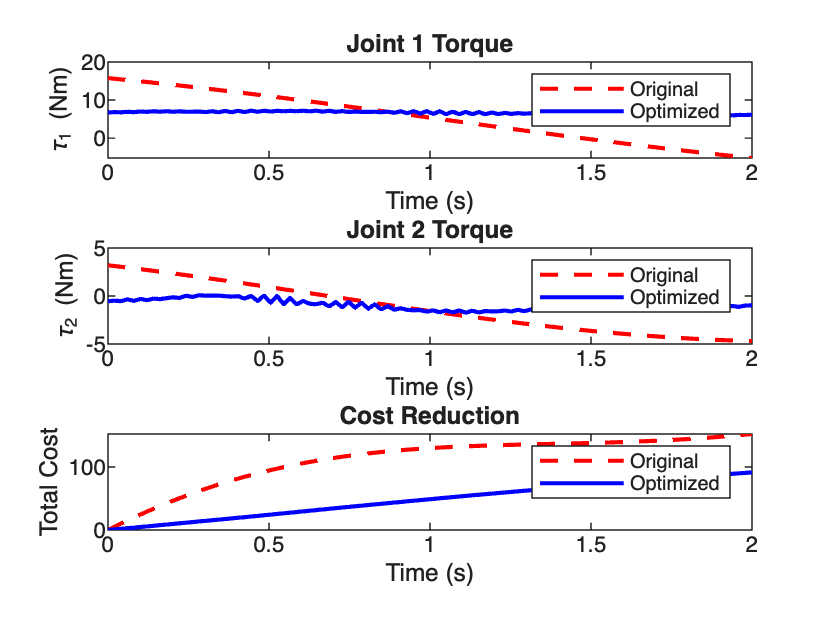

figure;
subplot(3,1,1)
plot(t, tau_ref(1,:), 'r--', t, tau_opt(1,:), 'b', 'LineWidth', 1.5)
ylabel('\tau_1 (Nm)')
xlabel('Time (s)')
legend('Original','Optimized')
title('Joint 1 Torque')

subplot(3,1,2)
plot(t, tau_ref(2,:), 'r--', t, tau_opt(2,:), 'b', 'LineWidth', 1.5)
ylabel('\tau_2 (Nm)')
xlabel('Time (s)')
legend('Original','Optimized')
title('Joint 2 Torque')

subplot(3,1,3)
plot(t, E_ref, 'r--', t, E_opt, 'b', 'LineWidth', 1.5)
xlabel('Time (s)')
ylabel('Total Cost')
title('Cost Reduction')
legend('Original','Optimized')


figure;

#### Joint Angle Tracking 

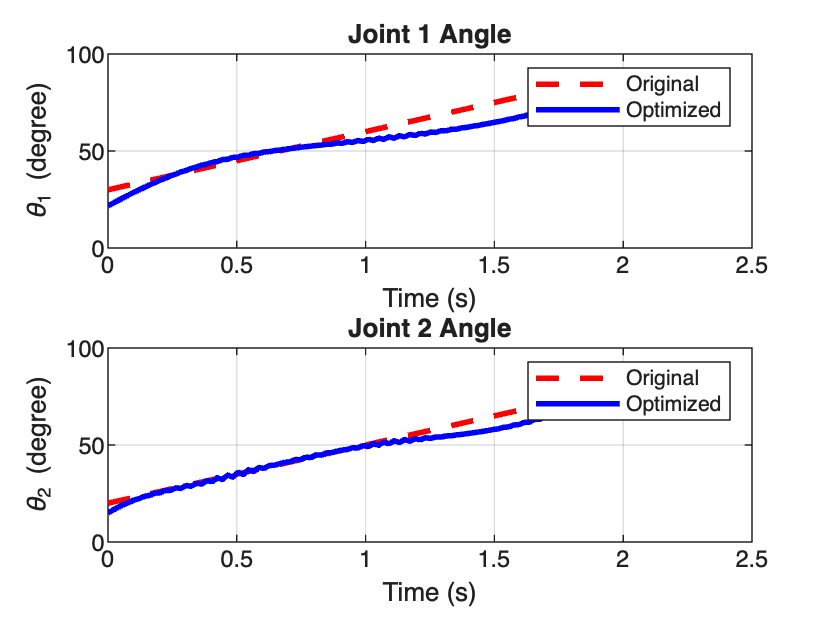

subplot(2,1,1);
plot(t, q_ref(1,:)*(180/pi), 'r--', 'LineWidth', 2); hold on;
plot(t, q_opt(1,:)*(180/pi), 'b', 'LineWidth', 2);
xlim([0 2.5]);
ylim([0 100]);
xlabel('Time (s)');
ylabel('\theta_1 (degree)');
title('Joint 1 Angle');
legend('Original', 'Optimized');
grid on;

subplot(2,1,2);
plot(t, q_ref(2,:)*(180/pi), 'r--', 'LineWidth', 2); hold on;
plot(t, q_opt(2,:)*(180/pi), 'b', 'LineWidth', 2);
xlim([0 2.5]);
ylim([0 100]);
xlabel('Time (s)');
ylabel('\theta_2 (degree)');
title('Joint 2 Angle');
legend('Original', 'Optimized');
grid on;

#### Function Definitions 

This function takes geometry of robot, position, velocity, and acceleration and computes the torque using the dynamics equation.


$$\tau=B(q)\ddot{q}+C(q,\dot{q})\dot{q}+G(q)$$


function tau = computeTorques(theta, theta_dot, theta_ddot, ...
    m_l1, m_l2, a_1, l_1, l_2, I_l1, I_l2, g)

    theta1 = theta(1); theta2 = theta(2);
    theta_dot1 = theta_dot(1); theta_dot2 = theta_dot(2);
    theta_ddot1 = theta_ddot(1); theta_ddot2 = theta_ddot(2);
    c2 = cos(theta2); s2 = sin(theta2); c1 = cos(theta1); c12 = cos(theta1+theta2);
    % B(q)
    b11 = I_l1+(m_l1*l_1^2)+I_l2+m_l2*(a_1^2+l_2^2+2*a_1*l_2*c2);
    b12 = I_l2+m_l2*(l_2^2+a_1*l_2*c2); b21 = b12; b22 = I_l2+m_l2*l_2^2;
    B = [b11 b12; b21 b22];
  
    % C(q,qdot)*qdot
    h1 = -2*m_l2*a_1*l_2*s2*theta_dot1*theta_dot2-m_l2*a_1*l_2*s2*theta_dot2^2;
    h2 =  m_l2*a_1*l_2*s2*theta_dot1^2;
    Cvec = [h1; h2];
    % G(q)
    g1 = (m_l1*l_1+m_l2*a_1)*g*c1+m_l2*l_2*g*c12; g2 = m_l2*l_2*g*c12;
    G = [g1; g2];
    tau = B*[theta_ddot1; theta_ddot2]+Cvec+G;
end

This function takes a proposed trajectory from the optimization and calculates the cost, which will be minimized through built in fmincon above.


$$J = \int\tau^2 \space dt+penalty$$


penalty = makes sure that the optimized trajectory starts and ends where specified

$cost = \int_{0}^{T} (\tau_{1}(t)^2+\tau_{2}(t)^2)\space dt$ cost metric the optimizer is minimizing 

trapz calculates a singular value, the total energy of the trajectory

Without penalty on choppy torque, optimizing cost only results in rapid changes in torque in order to minimize cost, adding a penalty to reduce the torque choppyness will increase cost but it is worth it for physical implmentation of this code to reduce wear and tear on the robot. 

function J = energyCost(x, t, q0, qf, dynamics)
    N = length(t);
    dt = t(2)-t(1);
    q = reshape(x, 2, N);
    penalty = 1000*(norm(q(:,1)-q0)^2 + norm(q(:,end)-qf)^2);
    qd = [gradient(q(1,:),dt); gradient(q(2,:),dt)]; % velocity
    qdd = [gradient(qd(1,:),dt); gradient(qd(2,:),dt)]; % acceleration

    torque = zeros(2, N);
    for i = 1:N
        torque(:,i) = dynamics(q(:,i), qd(:,i), qdd(:,i));
    end
    energy = trapz(t, sum(torque.^2,1));
    dtau = [gradient(torque(1,:), dt); gradient(torque(2,:), dt)];
    smooth_penalty = 1.5 * trapz(t, sum(dtau.^2,1)); %increase leading value to make less choppy
    J = energy + penalty+smooth_penalty;
end